# Numerical Calculus 4/4

-----

# 4. Multivariate differential equations

If there are multiple quantities to track, e.g., multiple molecules or species, then ODE models might be comprised of a *system of coupled ODEs*.


$$du/dt = f(u,w), dw/dt = g(u,w), u(0)=u_0, w(0)=w_0$$


Gene expression where the protein is an activator; u=RNA, w=protein.

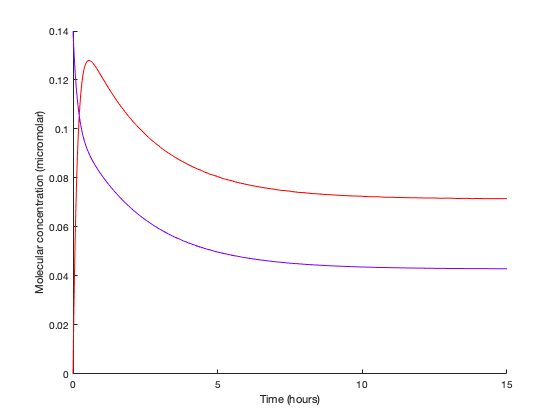

f =@(u,w) -5*u + 6*w   +0.1; 
g =@(u,w) -2*w + 1.2*u;

[T, X] = ode45(@(t,x)[f(x(1),x(2));g(x(1),x(2))], [0,15], [0.0,0.14] );

figure; hold on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for protein
ylabel('Molecular concentration (micromolar)')
xlabel('Time (hours)')

## 3.1 Phase plane and direction field

For a two-variable system, the equivalent of a phase line is a phase plane.

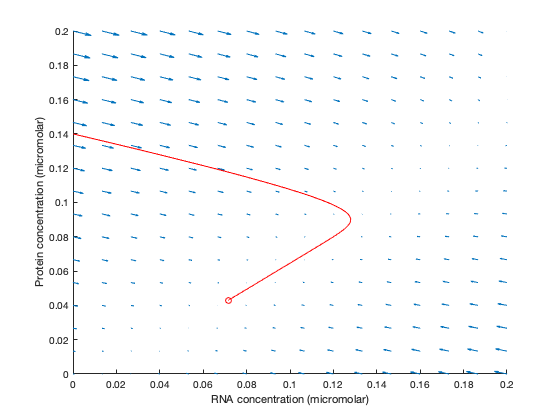

figure; hold on;
set(gca, 'xlim', [0, 0.2], 'ylim', [0,0.2])
ylabel('Protein concentration (micromolar)');
xlabel('RNA concentration (micromolar)')

uArray = linspace(0,0.2,16);
wArray = linspace(0,0.2,16);

[uMesh,wMesh] = meshgrid(uArray, wArray);

% the Matlab plot command for a field of arrows is:
quiver(uMesh, wMesh, f(uMesh, wMesh), g(uMesh,wMesh), 0.5)

plot(X(:,1),X(:,2),'-r')
plot(X(end,1),X(end,2), 'or')

 - there are two types of vectors: a position in the plane ([u,w]) and a direction+magnitude ([du/dt, dw/dt])

(Don't talk about nullclines.)

## 3.2 Mini exercise: Spirals and other flow patterns

Two-variable linear systems of ODEs can exhibit only a few patterns of behavior. 

- An attractive steady state where solutions spiral inwards

- An attractive steady state where solutions do not spiral in

- A repulsive steady state where solutions spiral outwards

- A repulsive steady state where solutions do not spiral out

- A pure oscillation

- One more category not contained in the list

Find parameters that give one of each.

You should be able to achieve these by only varying a,b,c and d below, exploring negative numbers too.

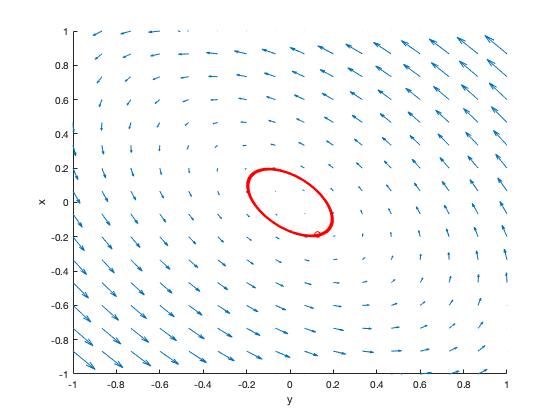


% parameters
a = -1;
b = -2;
d = 1;
c = 2;

% model equations
f =@(x,y) a*x + b*y; 
g =@(x,y) c*x + d*y;

[T, X] = ode45(@(t,x)[f(x(1),x(2));g(x(1),x(2))], [0,1000], [.1,.1] );

figure; hold on;
set(gca, 'xlim', [-1, 1], 'ylim', [-1, 1])
ylabel('x');
xlabel('y')

xArray = linspace(-1,1,16);
yArray = linspace(-1,1,16);

[xMesh,yMesh] = meshgrid(xArray, yArray);

% the Matlab plot command for a field of arrows is:
quiver(xMesh, yMesh, f(xMesh, yMesh), g(xMesh,yMesh))

plot(X(:,1),X(:,2),'-r')
plot(X(end,1),X(end,2), 'or')